# Train Variational Autoencoder (VAE) to Generate Images

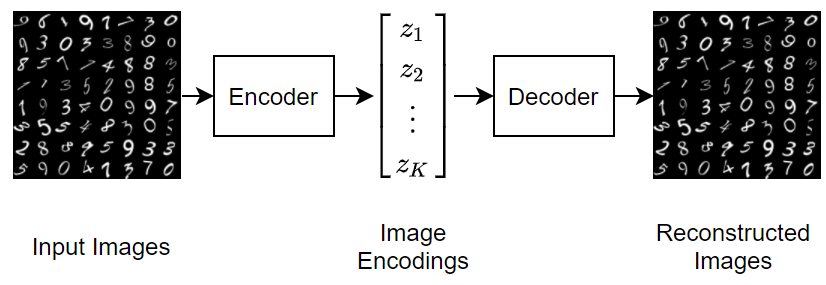

## Load Data

clear; clc;
imds = imageDatastore("img/bmp/bmp_1",IncludeSubfolders=true);
augmenter = imageDataAugmenter(RandXReflection=true);
augimds = augmentedImageDatastore([64 64],imds,DataAugmentation=augmenter);
XTrain = augimds;
XTest = augimds;

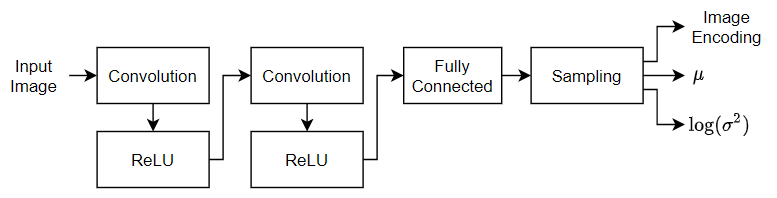

numLatentChannels = 16;
imageSize = [64 64 3];

layersE = [
    imageInputLayer(imageSize,Normalization="none")
    convolution2dLayer(3,32,Padding="same",Stride=2)
    reluLayer
    convolution2dLayer(3,64,Padding="same",Stride=2)
    reluLayer
    fullyConnectedLayer(2*numLatentChannels)
    sigmoidLayer];

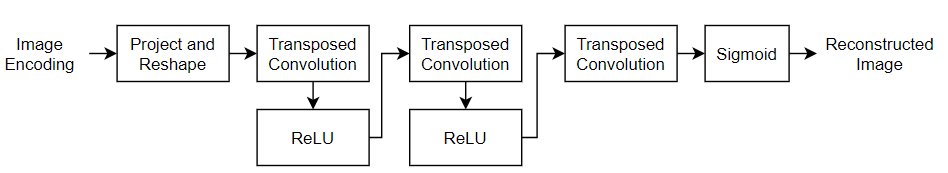

projectionSize = [7 7 64];
numInputChannels = size(imageSize,1);

layersD = [
    featureInputLayer(numLatentChannels)
    projectAndReshapeLayer(projectionSize)
    transposedConv2dLayer(3,64,Cropping="same",Stride=2)
    reluLayer
    transposedConv2dLayer(3,32,Cropping="same",Stride=2)
    reluLayer
    transposedConv2dLayer(3,numInputChannels,Cropping="same")
    samplingLayer];

netE = dlnetwork(layersE);
netD = dlnetwork(layersD);

## Specify Training Options

numEpochs = 30;
miniBatchSize = 128;
learnRate = 1e-3;

## Train Model

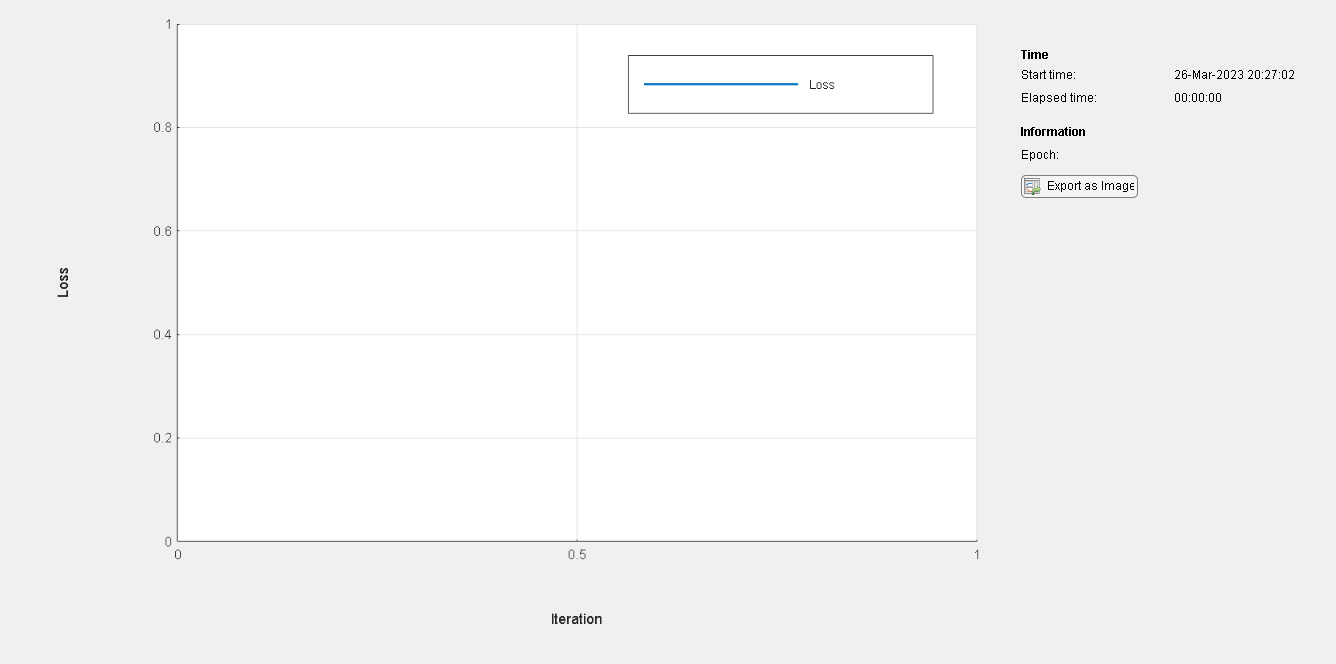

dsTrain = XTrain;%arrayDatastore(XTrain,IterationDimension=4);
numOutputs = 1;
mbq = minibatchqueue(dsTrain,numOutputs, ...
    MiniBatchSize = miniBatchSize, ...
    MiniBatchFcn=@preprocessMiniBatch, ...
    MiniBatchFormat="SSCB", ...
    PartialMiniBatch="discard");
trailingAvgE = []; trailingAvgSqE = [];
trailingAvgD = []; trailingAvgSqD = [];
numObservationsTrain = size(XTrain,4);
numIterationsPerEpoch = ceil(numObservationsTrain / miniBatchSize);
numIterations = numEpochs * numIterationsPerEpoch;
monitor = trainingProgressMonitor( ...
    Metrics="Loss", ...
    Info="Epoch", ...
    XLabel="Iteration");
epoch = 0;
iteration = 0;

% Loop over epochs.
while epoch < numEpochs && ~monitor.Stop
    epoch = epoch + 1;
    % Shuffle data.
    shuffle(mbq);
    % Loop over mini-batches.
    while hasdata(mbq) && ~monitor.Stop
        iteration = iteration + 1;
        % Read mini-batch of data.
        X = next(mbq);
        X = dlarray(X,'SSCB');
        % Evaluate loss and gradients.
        [loss,gradientsE,gradientsD] = dlfeval(@modelLoss,netE,netD,X);
        % Update learnable parameters.
        [netE,trailingAvgE,trailingAvgSqE] = adamupdate(netE, ...
            gradientsE,trailingAvgE,trailingAvgSqE,iteration,learnRate);
        [netD, trailingAvgD, trailingAvgSqD] = adamupdate(netD, ...
            gradientsD,trailingAvgD,trailingAvgSqD,iteration,learnRate);
        % Update the training progress monitor. 
        recordMetrics(monitor,iteration,Loss=loss);
        updateInfo(monitor,Epoch=epoch + " of " + numEpochs);
        monitor.Progress = 100*iteration/numIterations;
    end
end

## Test Network

dsTest = arrayDatastore(XTest,IterationDimension=4);
numOutputs = 1;

mbqTest = minibatchqueue(dsTest,numOutputs, ...
    MiniBatchSize = miniBatchSize, ...
    MiniBatchFcn=@preprocessMiniBatch, ...
    MiniBatchFormat="SSCB");
YTest = modelPredictions(netE,netD,mbqTest);
err = mean((XTest-YTest).^2,[1 2 3]);
figure
histogram(err)
xlabel("Error")
ylabel("Frequency")
title("Test Data")

## Generate New Images

numImages = 64;

ZNew = randn(numLatentChannels,numImages);
ZNew = dlarray(ZNew,"CB");

YNew = predict(netD,ZNew);
YNew = extractdata(YNew);
figure
I = imtile(YNew);
imshow(I)
title("Generated Images")

## Helper Functions

function [loss,gradientsE,gradientsD] = modelLoss(netE,netD,X)

% Forward through encoder.
[Z,mu,logSigmaSq] = forward(netE,X);

% Forward through decoder.
Y = forward(netD,Z);

% Calculate loss and gradients.
loss = elboLoss(Y,X,mu,logSigmaSq);
[gradientsE,gradientsD] = dlgradient(loss,netE.Learnables,netD.Learnables);

end

### ELBO Loss Function

function loss = elboLoss(Y,T,mu,logSigmaSq)
% Reconstruction loss.
reconstructionLoss = mse(Y,T);
% KL divergence.
KL = -0.5 * sum(1 + logSigmaSq - mu.^2 - exp(logSigmaSq),1);
KL = mean(KL);
% Combined loss.
loss = reconstructionLoss + KL;
end

function Y = modelPredictions(netE,netD,mbq)
Y = [];
% Loop over mini-batches.
while hasdata(mbq)
    X = next(mbq);
    % Forward through encoder.
    Z = predict(netE,X);
    % Forward through dencoder.
    XGenerated = predict(netD,Z);
    % Extract and concatenate predictions.
    Y = cat(4,Y,extractdata(XGenerated));
end
end

### Mini Batch Preprocessing Function

function X = preprocessMiniBatch(dataX)
% Concatenate.
X = cat(4,dataX{:});
end